**Part 1: **Demonstrate your ability to plot 1D functions given a range of input parameters.

Write a commented script that produces a labelled plot over the domain -1 < x < 10 for the following functions *on the same plot axis*:

- y = exp(-kx) when x>0, and zero otherwise.

- y = exp(-kx) sin(wx) when x>0, and zero otherwise. Choose an pair of parameter values within 0.2 < k < 0.5 and 2 < w < 5.

Your plot should be labelled to include any parameter values, and ideally your code will automatically handle *arbitrary* values of these parameters.

The functions should be plotted with distinct line-styles.

% Define parameters
k = 0.3;
w = 4;
x = (-1:10);

% Define y1(x) and y2(x) and symbolic variables
syms y1(x) y2(x)

% Define both functions as piecewise function
y1(x) = piecewise(x <= 0, 0, x > 0, exp(-k .* x));
y2(x) = piecewise(x <= 0, 0, x > 0, (exp(-k .* x) .* sin(w .* x)));

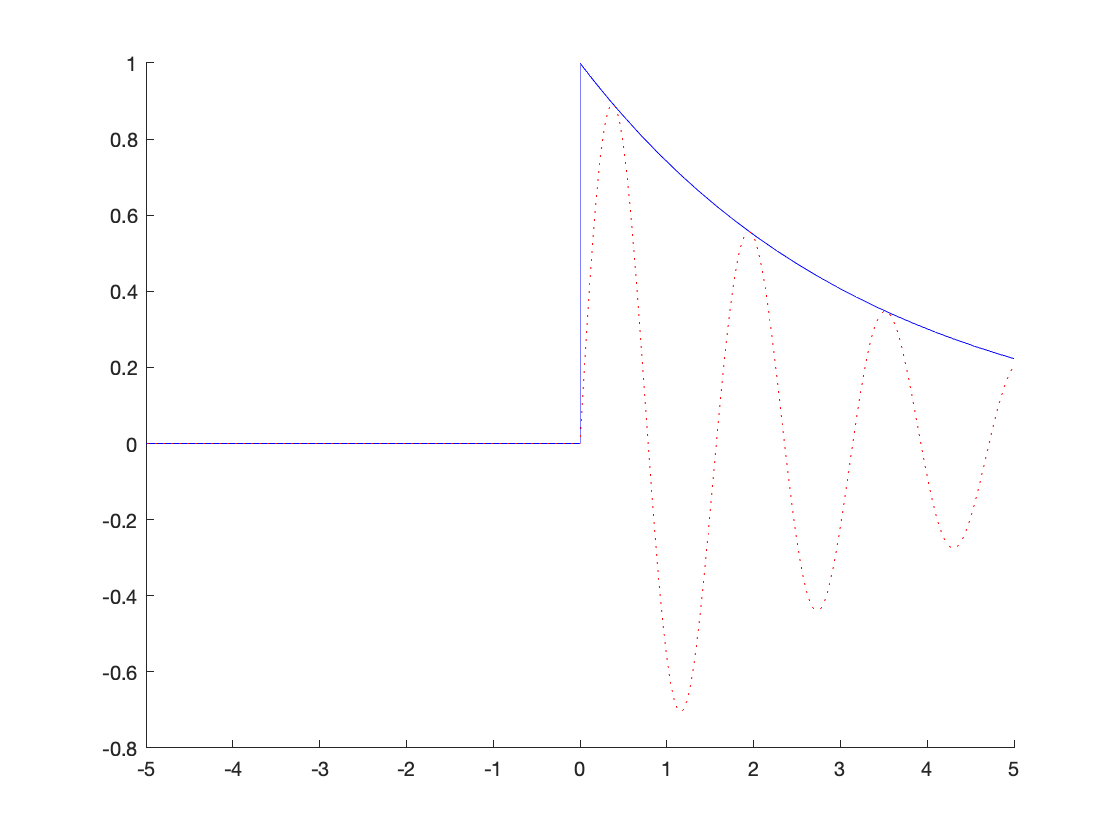

% Plot both functions with distinct line-styles
hold on;
fplot(y1, "b-");
fplot(y2, "r:");
hold off;

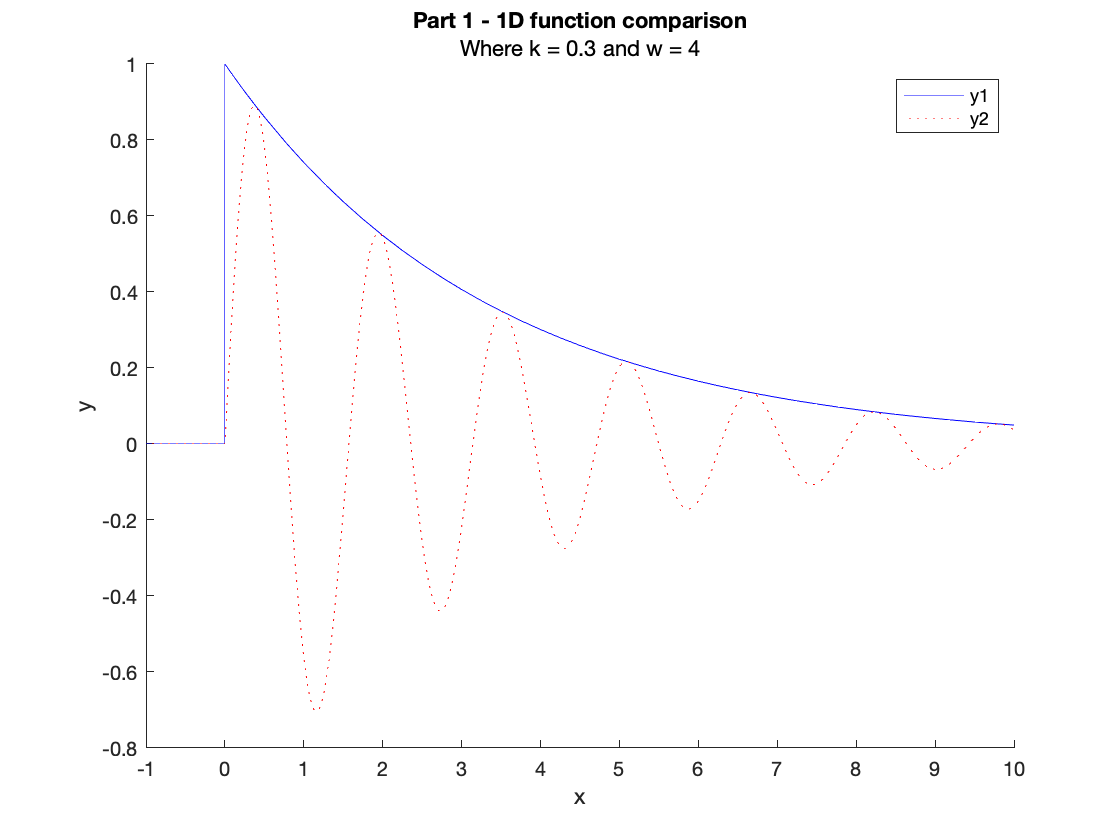

% Decorate graph
title("Part 1 - 1D function comparison");
subtitle("Where k = 0.3 and w = 4");
xlabel("x");
ylabel("y");
legend("y1", "y2");

% Restrict graph domain
xlim([-1, 10]);